# Read in Bode Data

bafile='/Users/madi/Documents/GitHub/MATLAB/Lab6/Bode/Lab 6-3 Bode.txt';
bafileID=fopen(bafile);
batextstuff=textscan(bafileID, '%s %s %s %s','Delimiter','\t');
fclose(bafileID);

bafreq=batextstuff{1,1};
bafreq=str2double(bafreq);
% bafreq=2.*pi.*bafreq;

bagain=batextstuff{1,2};
bagain=str2double(bagain);

baphase=batextstuff{1,3};
baphase=str2double(baphase);

## Variables

R=22000;
C1=3.68e-9;
C2=20.7e-9;
C3=14.4e-9;

## Read in CircuitLab Simulated data

clabfile='/Users/madi/Documents/GitHub/MATLAB/Lab6/CircuitLAB/6_3 CircuitLab.csv';
clabdata=readmatrix(clabfile);

clabfreq=clabdata(:,1);
clabgain=clabdata(:,2);
clabphase=clabdata(:,3);

## Theoretical

Gain

fth=logspace(1,5,200);
w=2.*pi.*fth;
s=1j.*w;

n=1;
d1=R.^3.*C1.*C2.*C3.*(s.^3);
d2=2.*(R.^2).*C1.*(C2+C3).*(s.^2);
d3=R.*(3.*C1+C3).*s;
d=d1+d2+d3+1;

gain=n./d;
absgain=abs(gain);

% Theoretical Phase
PhaseGRad=angle(gain);

## Plotting

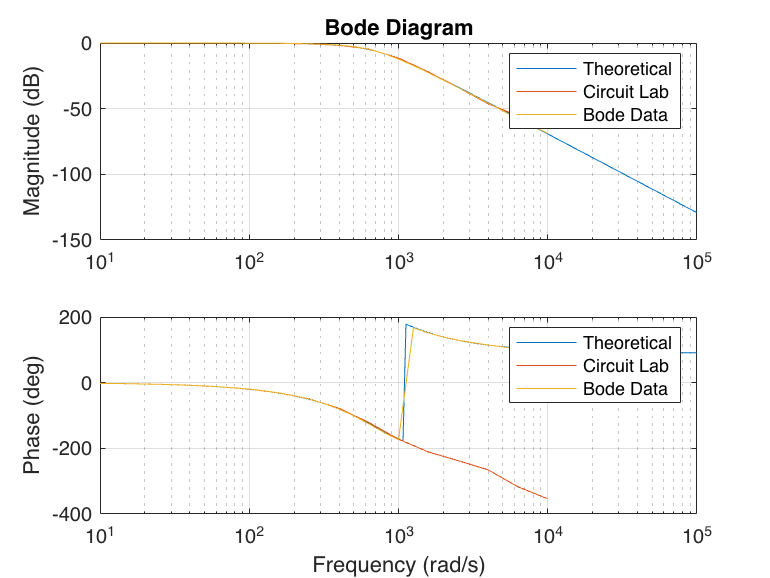

subplot(2,1,1)
semilogx(fth,20*log10(absgain),'DisplayName', 'Theoretical')
grid on
hold on
plot(clabfreq,clabgain,'DisplayName','CircuitLab')
hold on
semilogx(bafreq,bagain,'DisplayName','Bode Analyzer')
hold on

ylabel('Magnitude (dB)')
title ('Bode Diagram')
legend('Theoretical','Circuit Lab','Bode Data')
hold off



subplot(2,1,2)
semilogx(fth,PhaseGRad*(180/pi)) %% convert phase to degrees
grid on
hold on
plot(clabfreq,clabphase,'DisplayName','CircuitLab')
hold on
semilogx(bafreq,baphase,'DisplayName','Bode Analyzer')
hold on

ylabel('Phase (deg)')
xlabel('Frequency (rad/s)')
legend('Theoretical','Circuit Lab','Bode Data')
hold off